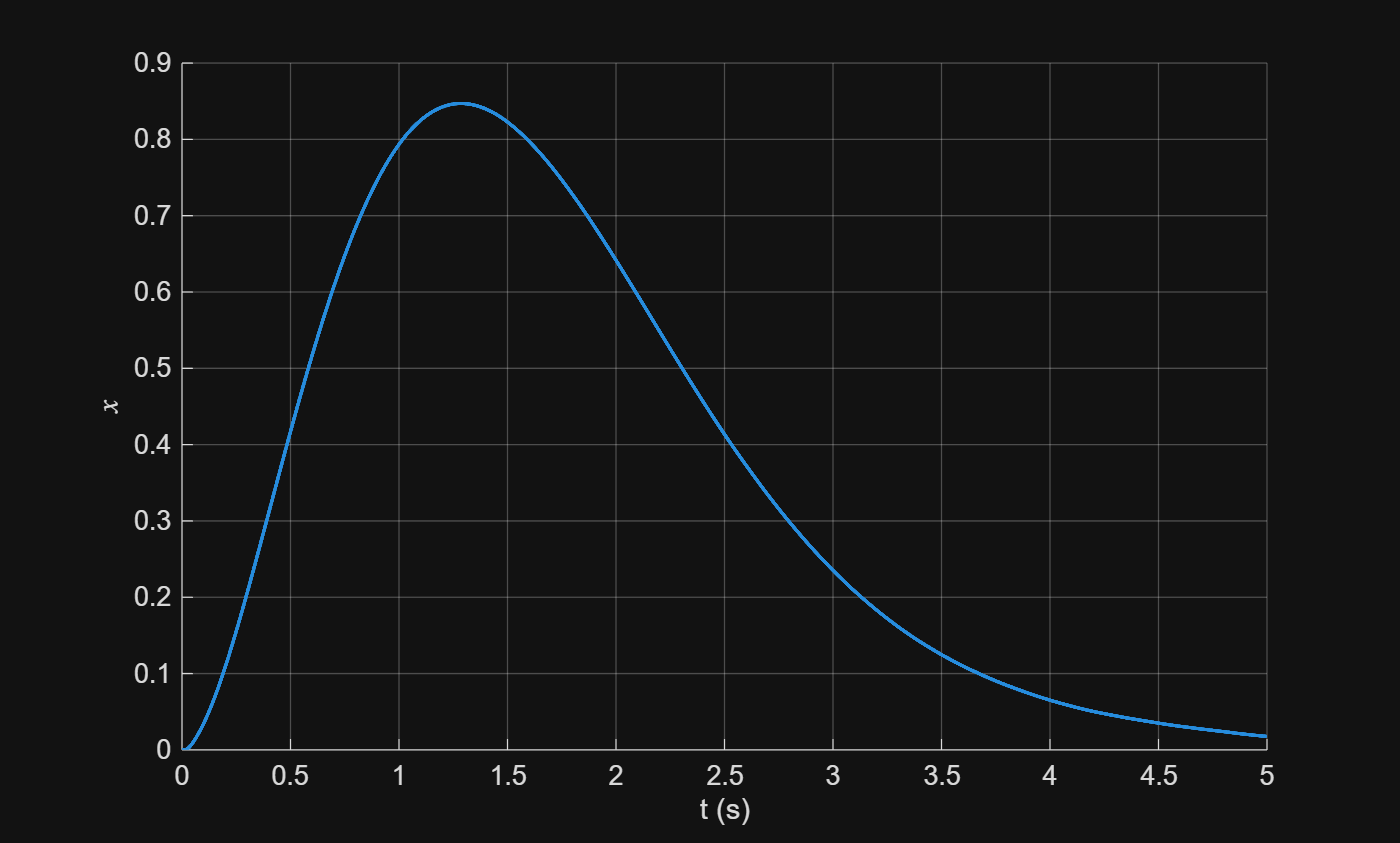

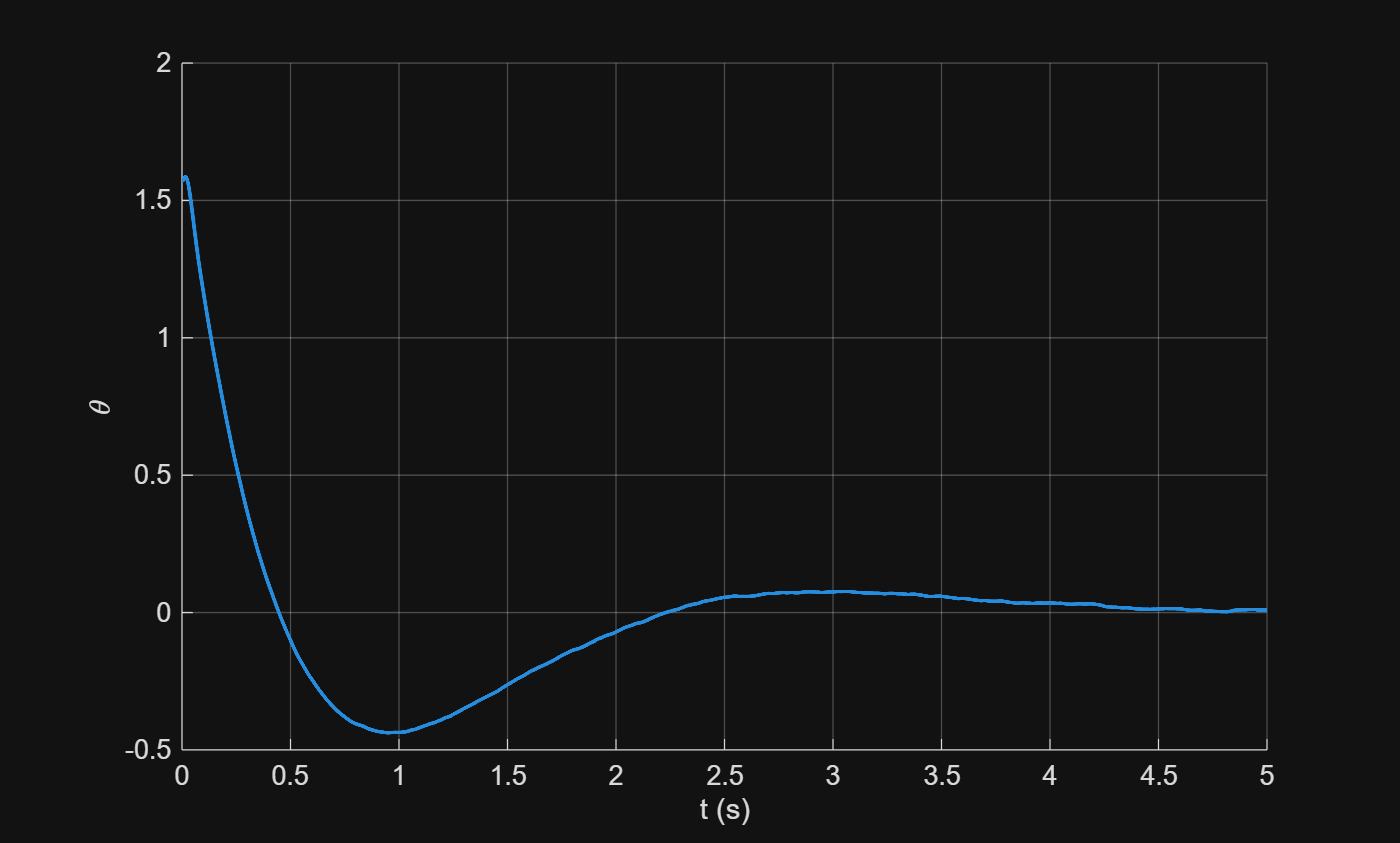

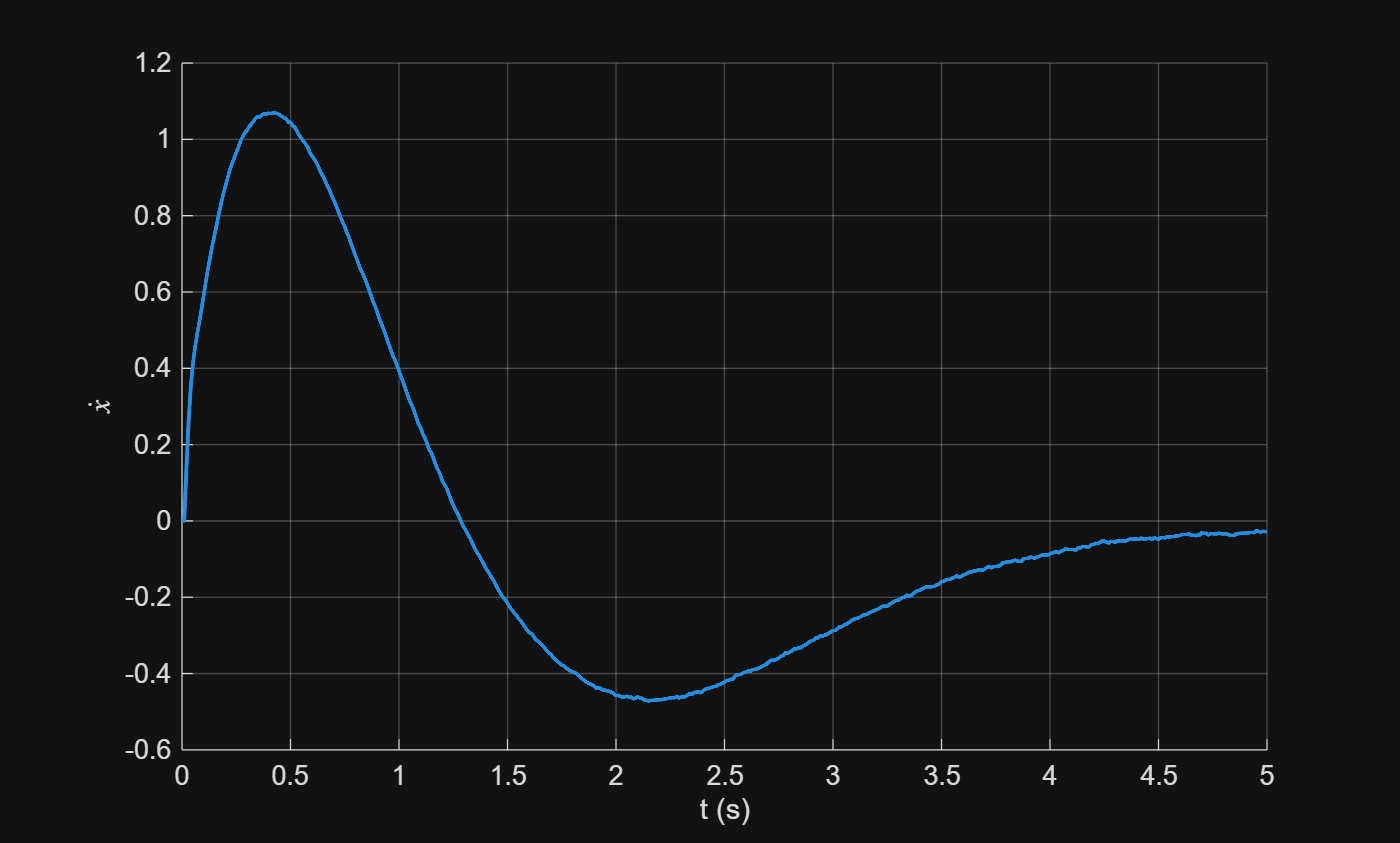

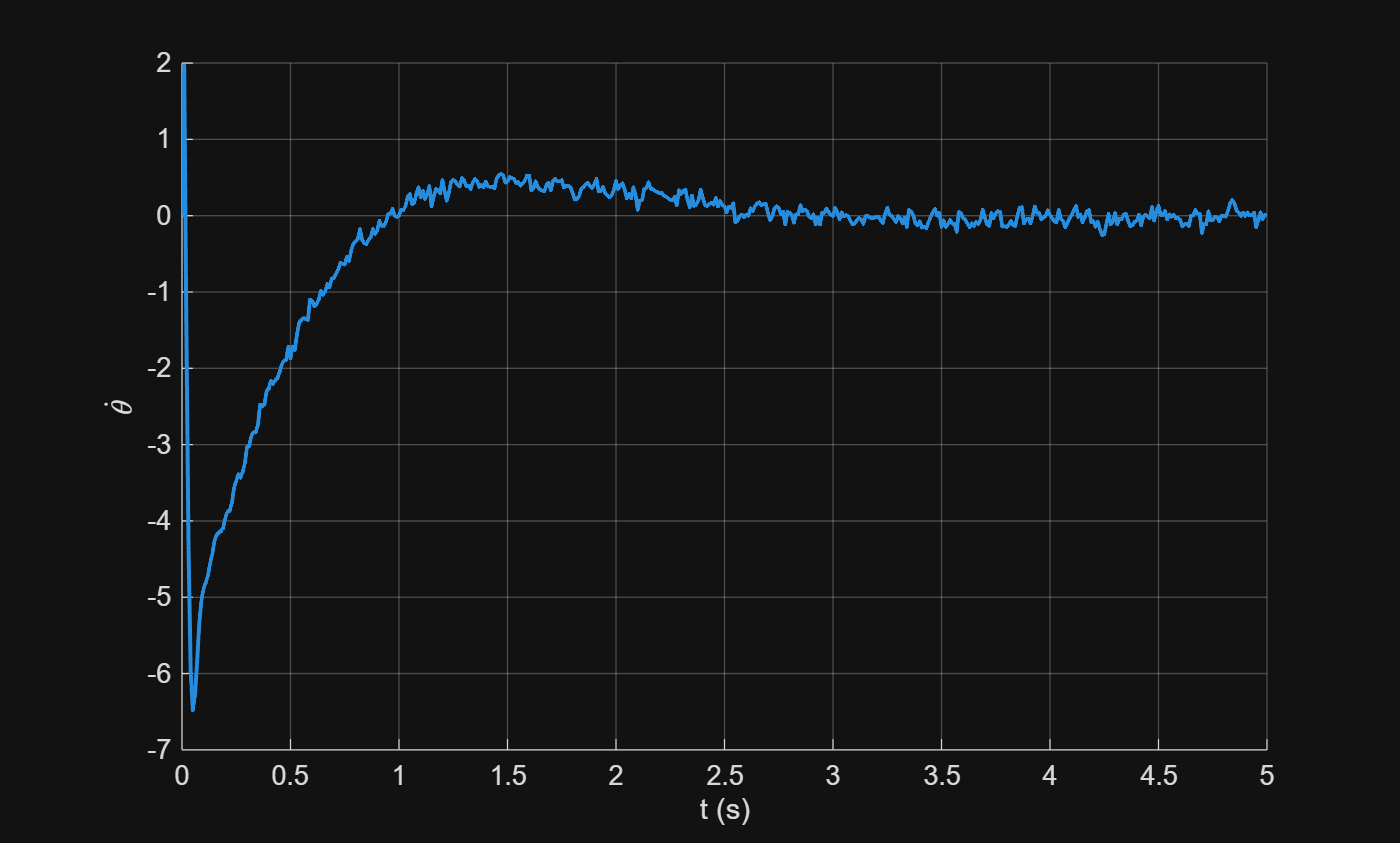

clear
close
clc
rng(1)

syms M_c m g l r b_v b_m J_m real
syms x(t) theta(t) x_dot theta_dot x_ddot theta_ddot
syms tau

params = [M_c; m; g; l; r; b_v; b_m; J_m];
values = [0.3; 0.1; 9.82; 0.05; 0.025; 0.01; 3.71*10^-5; 3.75*10^-7];
% values = [5; 1; 9.82*10; 0.3; 0.075; 0.01; 3.71*10^-5; 3.75*10^-7]/10;
% values = [0.3; 0.1; 9.82; 0.05; 0.025; 0; 0; 0];

% Large balancer
%values = 10*[0.3; 0.1; 9.82/10; 0.05; 0.025; 0.01; 3.71*10^-5; 3.75*10^-7];
%values = [5; 1; 9.82; 0.3; 0.075; 0.01; 3.71*10^-5; 3.75*10^-7];
% values = [5; 10; 9.82; 0.3; 0.075; 0; 0; 0];

% Differentiated variables
vars_diff = [diff(x,t,2); diff(x); x; diff(theta,t,2); diff(theta); theta];

% Inverse pendulum mass dynamics
posx_m = l*sin(theta) + x;
accx_m = diff(posx_m, t, 2); % second derivative

% Force required to accelerate the pendulums mass
F_pend = m*accx_m + b_v*diff(x, t);

% The force applied on the "cart" is
% the force generated by the motors
% minus the reaction force from the pendulum mass (x component)
F_mot = tau/r;
eq1 = (M_c + J_m/r^2)*diff(x,t,2) == F_mot - F_pend;

% Considering the load to be a point mass
% and tau is motor reaction torque
eq2 = m*l^2*diff(theta,t,2) == m*g*l*sin(theta) - m*l*diff(x,t,2)*cos(theta) - tau - b_m*diff(x,t)/r;

% Collect terms
eq1 = collect(lhs(eq1) - rhs(eq1), vars_diff);
eq2 = collect(lhs(eq2) - rhs(eq2), vars_diff);

% Express symbolically
syms x theta
vars_sym = [x_ddot; x_dot; x; theta_ddot; theta_dot; theta];
eq1 = subs(eq1, vars_diff, vars_sym);
eq2 = subs(eq2, vars_diff, vars_sym);

% Nonlinear model
[M, rest] = equationsToMatrix([eq1; eq2], [x_ddot; theta_ddot]);
accels = M \ rest;

f = formula([x_dot;
             theta_dot;
             accels(1);
             accels(2)]);

model = subs(f, formula(params), values);
pendulum_dynamics = matlabFunction(model, 'Vars', {x, theta, x_dot, theta_dot, tau});

% Parameter estimation
% Bleh...

% Linearized model
op_state = [0; 0; 0; 0];
op_u = 0;

x_sym = formula([x; theta; x_dot; theta_dot]);
u_sym = tau;

A_sym = jacobian(f, x_sym);
B_sym = jacobian(f, u_sym);

A_lin = subs(A_sym, [x_sym; u_sym], [op_state; op_u]);
B_lin = subs(B_sym, [x_sym; u_sym], [op_state; op_u]);

A = double(subs(A_lin, formula(params), values));
B = double(subs(B_lin, formula(params), values));
C = eye(4);

Ts = 0.01;

sys = ss(A,B,C,0);
dsys = c2d(sys, Ts);
Ad = dsys.A;
Bd = dsys.B;

Obsv = rank(obsv(sys));
Cont = rank(ctrb(sys));

Qx = [1, 0, 0, 0;
      0, 1, 0, 0;
      0, 0, 1, 0;
      0, 0, 0, 1];
Qu = 1;

[Kd, ~, ~] = dlqr(dsys.A, dsys.B, Qx, Qu);

% Check stability
eig(dsys.A - dsys.B*Kd);

% Simulate nonlinear system
t_end = 5;
T = 0:Ts:t_end;
P0 = 1*eye(4);
x0 = [0; pi/2; 0; 0];
%x0 = [0; 0.5; 0; 0];

xd = x0;
xd_filtered = x0;
Pd = P0;
ud_prev = 0;

x = x0;
x_filtered = x0;
P = P0;
u_prev = 0;

Q = 0.05*eye(4);
H = eye(4);
R = 0.05*eye(4);

% Assume zero mean measurement noise
% rough values:
sigma_x = 0.01*pi/(180*0.025);
sigma_th = 0.05*pi/180;
sigma_x_dot = 0.1*pi/(180*0.025);
sigma_th_dot = 0.05*pi/180;
sigma = [sigma_x; sigma_th; sigma_x_dot;
         sigma_th_dot];

t_traj = [];
t_meas = [];
X = [];
X_filtered = [];
P_filtered = [];
Y = [];
U = [];

Xd = x0.';
Ud = 0;

for k = 1:length(T)-1

    % Compute noise, use in linear and nonlinear model
    n = normrnd(0, sigma);
    
    % Linear simulator
    yd = xd + n;

    [xd_filtered, Pd] = kalmanFilter(yd, H, R, xd_filtered, Pd, Ad, Q, Bd, ud_prev);
    ud = -Kd*xd_filtered;
    ud_prev = ud;

    % Simulate system
    xd = Ad*xd + Bd*ud;
    
    Xd = [Xd; xd.'];
    Ud = [Ud; ud];

    % Nonlinear simulator

    % Integrate nonlinear system over [T(k), T(k+1)] with constant u
    ode = @(t,x) pendulum_dynamics(x(1), x(2), x(3), x(4), u_prev);
    [tk, xk] = ode45(ode, [T(k), T(k+1)], x); % Simulate from "true" state
    x = xk(end,:).';
    y = x + n;
    
    % Predict and filter from "x0"
    [x_filtered, P] = kalmanFilter(y, H, R, x_filtered, P, Ad, Q, Bd, u_prev);
    u = -Kd*x_filtered;
    u_prev = u;

    % Append trajectory
    t_traj = [t_traj; tk];
    X = [X; xk];
    
    % Store states
    t_meas = [t_meas; tk(1)];
    Y = [Y; y.'];
    U = [U; u*ones(length(tk),1)];
    X_filtered = [X_filtered; x_filtered.'];

end

%% Plots
states = ["$x$"; "$\theta$"; "$\dot{x}$"; "$\dot{\theta}$"];
for i = 1:size(X,2)
    % Interpolate linear model to nonlinear size
    % for error comparison
    Xd_lerp = interp1(T, Xd(:,i), t_traj);
    figure;
    hold on
    plot(t_traj, X(:,i), 'LineWidth', 1.5);
    %plot(T, Xd(:,i), 'LineWidth', 1.5, 'Color', 'r');
    % relative error
    % plot(t_traj, (X(:,i) - Xd_lerp), 'LineWidth', 1.5, 'Color', 'y')
    % scatter(t_meas, Y(:,i), 5, 'filled');
    % plot(t_meas, X_filtered(:,i), 'LineWidth',1.5);

    xlabel('t (s)');
    ylabel(states(i),'Interpreter','latex');
    grid on;
    hold off
end

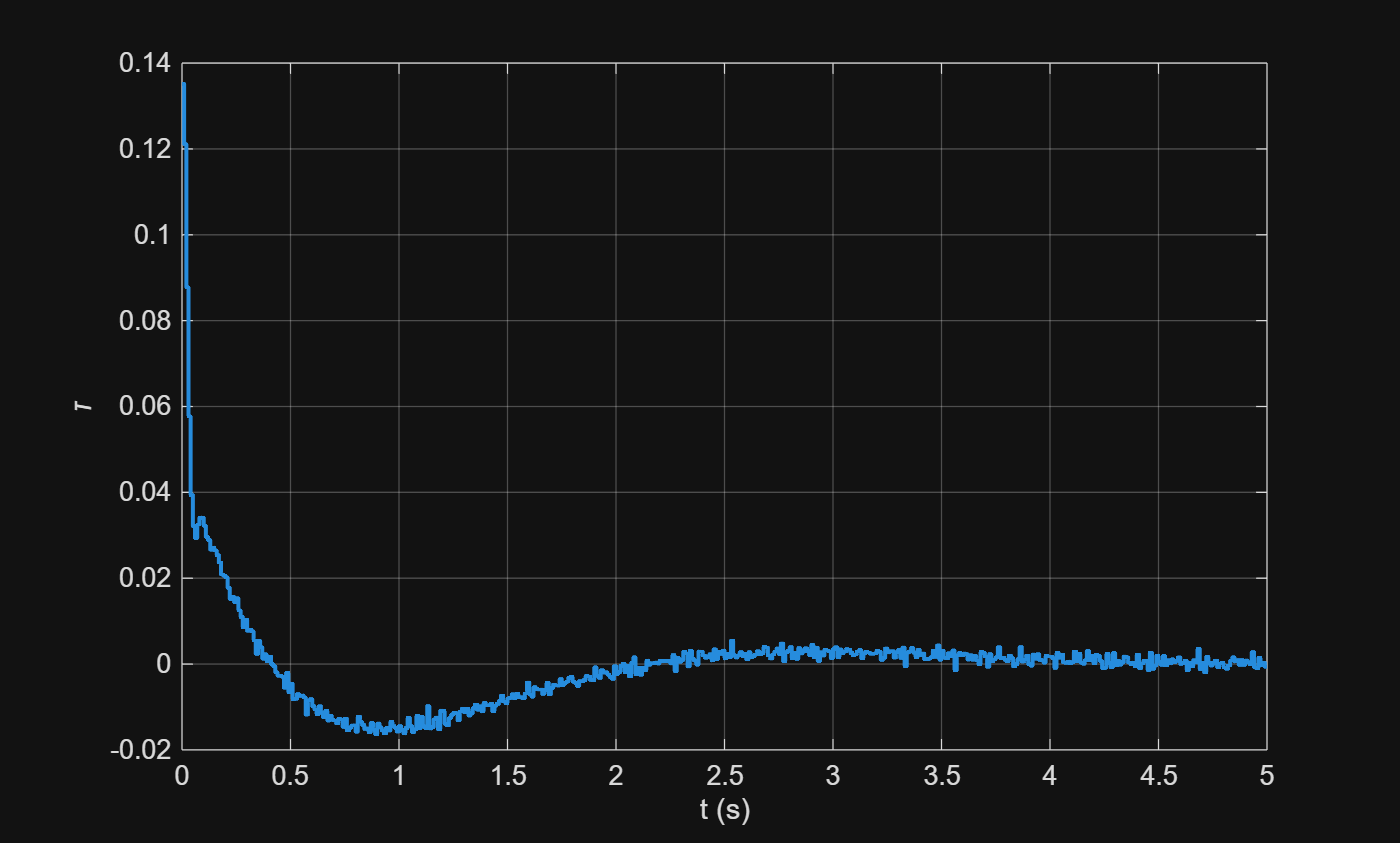


figure(2)
plot(t_traj, U, 'LineWidth', 1.5);
xlabel('t (s)');
ylabel('\tau');
grid on;

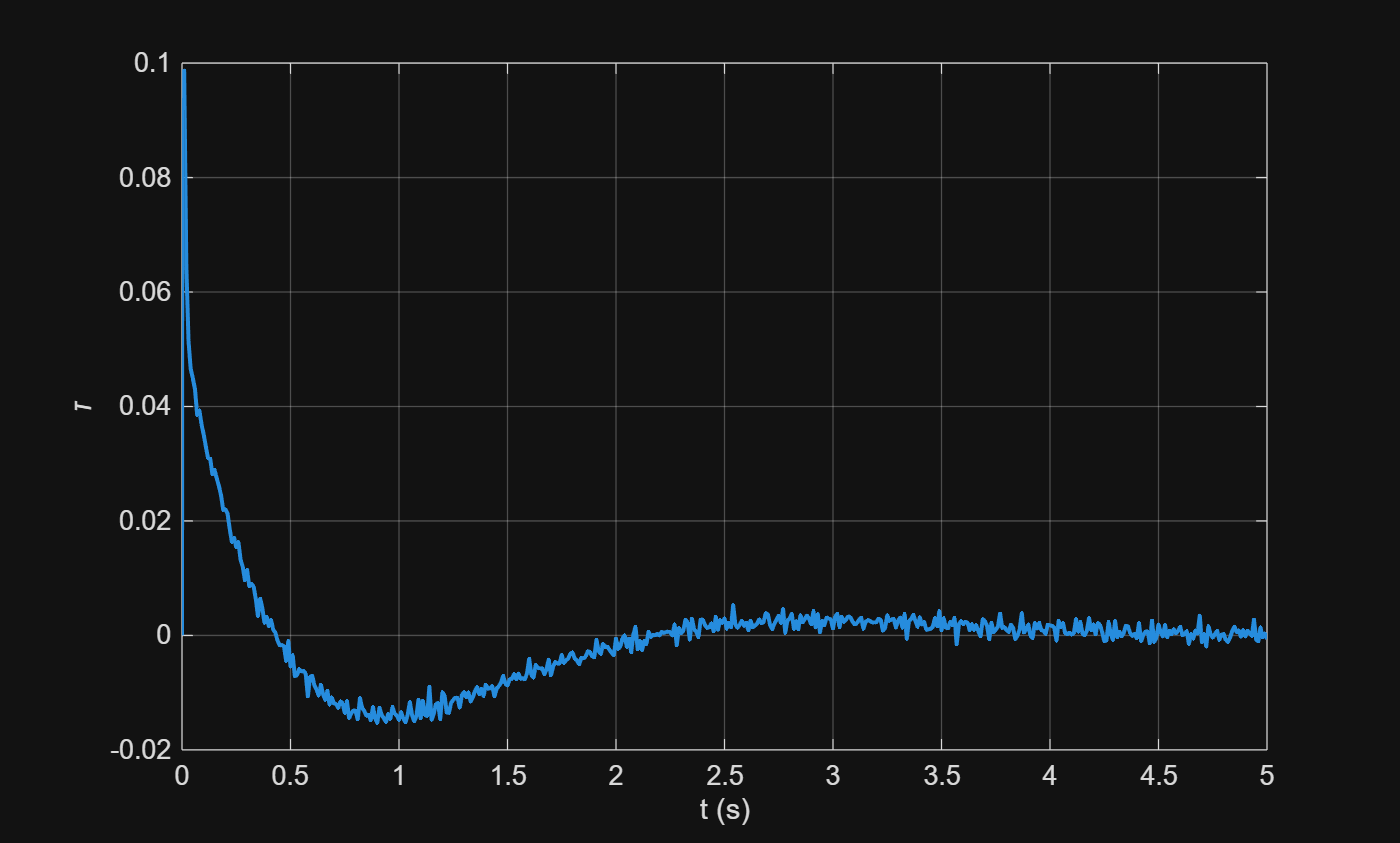


figure(3)
plot(T, Ud, 'LineWidth', 1.5);
xlabel('t (s)');
ylabel('\tau');
grid on;


% Conclusion:
% The difference between the linear and the nonlinear model is affected by
% both nonlinearities and the size of the main parameters of the robot. For
% a small balancing robot it turns out the nonlinearities also become small
% the LQR works well on both the linear and nonlinear model. How well the
% Controller works also depends on the relationship between the different
% parameters aswell as the magnitude of the values, but this could be
% because of nonlinearities in the parameters (scaled differently).

% For small angles up to about
% This is because the nonlinear effects are small even when
% The model is well outside the linearized